1번 문제

clear;
clc;

%a번 문제
Hour=[6;7;8;9;10;11;12;13;14;15;16;17];
SolarGen=[0.5;1.2;2.4;3.8;4.6;5.1;5.4;5.0;4.2;3.0;1.7;0.8];
Demand=[1.8;2.0;2.3;2.7;3.1;3.4;3.8;4.0;3.7;3.4;3.0;2.5];
Battery=[3.2;3.0;3.1;3.8;4.5;5.2;5.9;6.3;6.5;6.1;5.4;4.7];

%b번 문제
A=[Hour SolarGen Demand Battery];
disp(A);

    6.0000    0.5000    1.8000    3.2000
    7.0000    1.2000    2.0000    3.0000
    8.0000    2.4000    2.3000    3.1000
    9.0000    3.8000    2.7000    3.8000
   10.0000    4.6000    3.1000    4.5000
   11.0000    5.1000    3.4000    5.2000
   12.0000    5.4000    3.8000    5.9000
   13.0000    5.0000    4.0000    6.3000
   14.0000    4.2000    3.7000    6.5000
   15.0000    3.0000    3.4000    6.1000
   16.0000    1.7000    3.0000    5.4000
   17.0000    0.8000    2.5000    4.7000




%c번 문제
writematrix(A,'solarsystem.txt');

%d번 문제
B=load('solarsystem.txt');
disp(B);

    6.0000    0.5000    1.8000    3.2000
    7.0000    1.2000    2.0000    3.0000
    8.0000    2.4000    2.3000    3.1000
    9.0000    3.8000    2.7000    3.8000
   10.0000    4.6000    3.1000    4.5000
   11.0000    5.1000    3.4000    5.2000
   12.0000    5.4000    3.8000    5.9000
   13.0000    5.0000    4.0000    6.3000
   14.0000    4.2000    3.7000    6.5000
   15.0000    3.0000    3.4000    6.1000
   16.0000    1.7000    3.0000    5.4000
   17.0000    0.8000    2.5000    4.7000




%e번 문제
hour=B(:,1);
solar=B(:,2);
demand=B(:,3);
battery=B(:,4);

%f번 문제
netPower=solar-demand;
disp(netPower);

   -1.3000
   -0.8000
    0.1000
    1.1000
    1.5000
    1.7000
    1.6000
    1.0000
    0.5000
   -0.4000
   -1.3000
   -1.7000



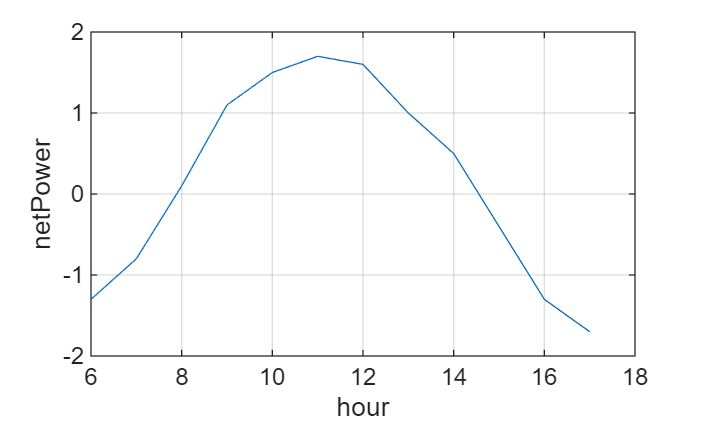


%g번 문제
figure;
plot(hour,netPower);
xlabel('hour');
ylabel('netPower');
grid on;

2번 문제

clear;
clc;

%a번 문제
D=[1 2.1 8 12;2 3.4 13 19;3 1.8 7 10;4 5.2 21 31;5 4.7 19 28;6 6.0 25 36;7 3.1 12 18;8 5.8 24 35];

%b번 문제
writematrix(D,'drone_delivery.txt');
B=load('drone_delivery.txt');
disp(B);

    1.0000    2.1000    8.0000   12.0000
    2.0000    3.4000   13.0000   19.0000
    3.0000    1.8000    7.0000   10.0000
    4.0000    5.2000   21.0000   31.0000
    5.0000    4.7000   19.0000   28.0000
    6.0000    6.0000   25.0000   36.0000
    7.0000    3.1000   12.0000   18.0000
    8.0000    5.8000   24.0000   35.0000




%c번 문제
RouteID=B(:,1);
DistanceKm=B(:,2);
TimeMin=B(:,3);
BatteryUsed=B(:,4);

%d번 문제
speed=DistanceKm./TimeMin;
disp(speed);

    0.2625
    0.2615
    0.2571
    0.2476
    0.2474
    0.2400
    0.2583
    0.2417




%e번 문제
BatteryPerKm=BatteryUsed./DistanceKm;
disp(BatteryPerKm);

    5.7143
    5.5882
    5.5556
    5.9615
    5.9574
    6.0000
    5.8065
    6.0345




%f번 문제
idx=BatteryPerKm>6;
result=[RouteID(idx) DistanceKm(idx) BatteryPerKm(idx)];
disp(result);

    8.0000    5.8000    6.0345



3번 문제

clear;
clc;

%a번 문제
Zone=["Z1";"Z2";"Z3";"Z4";"Z5";"Z6";"Z7";"Z8"];
Temp=[22.5;24.1;21.8;25.3;23.7;26.0;22.9;24.8];
Humidity=[61;58;67;55;62;53;65;57];
Light=[420;460;390;520;480;550;410;500];
CO2=[510;540;495;610;575;640;520;600];

%b번 문제
Farm=table(Zone,Temp,Humidity,Light,CO2);
disp(Farm);

    Zone    Temp    Humidity    Light    CO2
    ____    ____    ________    _____    ___

    "Z1"    22.5       61        420     510
    "Z2"    24.1       58        460     540
    "Z3"    21.8       67        390     495
    "Z4"    25.3       55        520     610
    "Z5"    23.7       62        480     575
    "Z6"      26       53        550     640
    "Z7"    22.9       65        410     520
    "Z8"    24.8       57        500     600




%c번 문제
Farm.EnvIndex=0.4*Farm.Temp+0.01*Farm.Light+0.02*Farm.CO2;
disp(Farm);

    Zone    Temp    Humidity    Light    CO2    EnvIndex
    ____    ____    ________    _____    ___    ________

    "Z1"    22.5       61        420     510      23.4  
    "Z2"    24.1       58        460     540     25.04  
    "Z3"    21.8       67        390     495     22.52  
    "Z4"    25.3       55        520     610     27.52  
    "Z5"    23.7       62        480     575     25.78  
    "Z6"      26       53        550     640      28.7  
    "Z7"    22.9       65        410     520     23.66  
    "Z8"    24.8       57        500     600     26.92  




%d번 문제
HighEnv=Farm(Farm.EnvIndex>=25,:);

%e번 문제
disp(HighEnv(:, {'Zone','Temp','Light','EnvIndex'}));

    Zone    Temp    Light    EnvIndex
    ____    ____    _____    ________

    "Z2"    24.1     460      25.04  
    "Z4"    25.3     520      27.52  
    "Z5"    23.7     480      25.78  
    "Z6"      26     550       28.7  
    "Z8"    24.8     500      26.92  



4번 문제

clear;
clc;

%a번 문제
Machine=["M1";"M2";"M3";"M4";"M5";"M6";"M7";"M8";"M9";"M10"];
Vibration=[1.8;2.4;1.5;3.1;2.7;1.9;3.5;2.2;1.6;2.9];
Temp=[68;72;65;78;74;69;82;71;66;76];
Power=[4.5;5.1;4.2;6.3;5.7;4.8;6.8;5.0;4.4;6.0];
Defect=[2;5;1;8;6;3;10;4;1;7];
Factory=table(Machine,Vibration,Temp,Power,Defect);
disp(Factory);

    Machine    Vibration    Temp    Power    Defect
    _______    _________    ____    _____    ______

     "M1"         1.8        68      4.5        2  
     "M2"         2.4        72      5.1        5  
     "M3"         1.5        65      4.2        1  
     "M4"         3.1        78      6.3        8  
     "M5"         2.7        74      5.7        6  
     "M6"         1.9        69      4.8        3  
     "M7"         3.5        82      6.8       10  
     "M8"         2.2        71        5        4  
     "M9"         1.6        66      4.4        1  
     "M10"        2.9        76        6        7  




%b번 문제
Factory.RiskScore=Factory.Vibration.*Factory.Temp./Factory.Power;
disp(Factory);

    Machine    Vibration    Temp    Power    Defect    RiskScore
    _______    _________    ____    _____    ______    _________

     "M1"         1.8        68      4.5        2         27.2  
     "M2"         2.4        72      5.1        5       33.882  
     "M3"         1.5        65      4.2        1       23.214  
     "M4"         3.1        78      6.3        8       38.381  
     "M5"         2.7        74      5.7        6       35.053  
     "M6"         1.9        69      4.8        3       27.312  
     "M7"         3.5        82      6.8       10       42.206  
     "M8"         2.2        71        5        4        31.24  
     "M9"         1.6        66      4.4        1           24  
     "M10"        2.9        76        6        7       36.733  




%c번 문제
RiskMachines=Factory(Factory.RiskScore>=35 & Factory.Defect>=6,:);

%d번 문제
disp(RiskMachines(:,{'Machine','RiskScore','Defect'}));

    Machine    RiskScore    Defect
    _______    _________    ______

     "M4"       38.381         8  
     "M5"       35.053         6  
     "M7"       42.206        10  
     "M10"      36.733         7  




%e번 문제
writetable(Factory,'factoryrisk.csv');

5번 문제

clear;
clc;


%a번 문제
url="https://archive.ics.uci.edu/ml/machine-learning-databases/abalone/abalone.data";

%b번 문제
data=readtable(url,'FileType','text','ReadVariableNames',false);

%c번 문제
data.Properties.VariableNames={'Sex','Length','Diameter','Height','WholeWeight','ShuckedWeight','VisceraWeight','ShellWeight','Rings'};

%d번 문제
smallTable=data(:,{'WholeWeight','ShellWeight','Rings'});
disp(smallTable);

    WholeWeight    ShellWeight    Rings
    ___________    ___________    _____

       0.514           0.15        15  
      0.2255           0.07         7  
       0.677           0.21         9  
       0.516          0.155        10  
       0.205          0.055         7  
      0.3515           0.12         8  
      0.7775           0.33        20  
       0.768           0.26        16  
      0.5095          0.165         9  
      0.8945           0.32        19  
      0.6065           0.21        14  
       0.406          0.135        10  
      0.5415           0.19        11  
      0.6845          0.205        10  
      0.4755          0.185        10  
      0.6645           0.24        12  
      0.2905          0.115         7  
       0.451           0.13        10  
      0.2555            0.1         7  
       0.381          0.115         9  
      0.2455          0.075        11  
      0.2255          0.085        10  
      0.9395           0.27        12  


%e번 문제
OldMale=data(data.Sex=="M" & data.Rings>=15,:);

%f번 문제
disp(OldMale(:,{'Sex','Length','WholeWeight','Rings'}));

     Sex     Length    WholeWeight    Rings
    _____    ______    ___________    _____

    {'M'}    0.455        0.514        15  
    {'M'}    0.605       0.9365        15  
    {'M'}    0.665        1.338        18  
    {'M'}    0.595       1.3175        21  
    {'M'}    0.565       0.8115        15  
    {'M'}    0.695        1.494        15  
    {'M'}     0.55        0.843        15  
    {'M'}     0.53        0.883        15  
    {'M'}      0.7       1.7255        19  
    {'M'}     0.71        1.959        18  
    {'M'}    0.595        1.262        17  
    {'M'}     0.65       1.3445        16  
    {'M'}     0.59        1.053        15  
    {'M'}    0.645        1.514        16  
    {'M'}     0.64        1.368        21  
    {'M'}     0.64       1.3035        16  
    {'M'}     0.56        0.922        15  
    {'M'}    0.625       1.4455        22  
    {'M'}    0.565       0.9425        17  
    {'M'}      0.6       1.2415        15  
    {'M'}     0.56        1.011

6번 문제

%a번 문제
Abalonetable=data;

%b번 문제
Abalonetable.ShellRatio=Abalonetable.ShellWeight./Abalonetable.WholeWeight;

%c번 문제
HardShell= Abalonetable(Abalonetable.ShellRatio>=0.25 & Abalonetable.Rings>=12,:);

%d번 문제
disp(HardShell(:,{'Sex','WholeWeight','ShellWeight','ShellRatio','Rings'}));

     Sex     WholeWeight    ShellWeight    ShellRatio    Rings
    _____    ___________    ___________    __________    _____

    {'M'}       0.514           0.15        0.29183       15  
    {'F'}      0.7775           0.33        0.42444       20  
    {'F'}       0.768           0.26        0.33854       16  
    {'F'}      0.8945           0.32        0.35774       19  
    {'F'}      0.6065           0.21        0.34625       14  
    {'M'}      0.6645           0.24        0.36117       12  
    {'F'}      0.9395           0.27        0.28739       12  
    {'M'}       0.931           0.28        0.30075       12  
    {'M'}      0.9365          0.295          0.315       15  
    {'F'}       1.639           0.46        0.28066       15  
    {'M'}       1.338           0.35        0.26158       18  
    {'F'}       1.798          0.455        0.25306       19  
    {'F'}      1.7095           0.49        0.28663       13  
    {'F'}       1.217           0.34        0.27938   


%e번 문제
ratioData=Abalonetable{:,'ShellRatio'};

7번 문제

clear;
clc;

%a번 문제
url="https://archive.ics.uci.edu/ml/machine-learning-databases/forest-fires/forestfires.csv";

%b번 문제
data=readtable(url);

%c번 문제
temp=data.temp;
RH=data.RH;
wind=data.wind;
rain=data.rain;
area=data.area;

%d번 문제
HotDry=temp>=25 & RH<=35;
HotDryFires=data(HotDry,:);

%e번 문제
disp(HotDryFires(:,{'month','day','temp','RH','wind','area'}));

     month       day      temp    RH    wind     area 
    _______    _______    ____    __    ____    ______

    {'sep'}    {'wed'}    26.4    21    4.5          0
    {'sep'}    {'sat'}    30.2    24    2.7          0
    {'sep'}    {'fri'}    25.4    24    3.6          0
    {'sep'}    {'wed'}    25.9    24      4          0
    {'sep'}    {'thu'}    27.7    24    2.2          0
    {'sep'}    {'fri'}    27.6    30    1.3          0
    {'sep'}    {'thu'}    25.4    27    2.2          0
    {'aug'}    {'thu'}    27.4    22      4        0.9
    {'sep'}    {'sat'}    29.6    27    2.7       1.46
    {'sep'}    {'sat'}    28.6    27    2.2       1.61
    {'sep'}    {'sun'}    28.3    26    3.1       64.1
    {'sep'}    {'wed'}    26.4    21    4.5      88.49
    {'sep'}    {'sun'}    27.8    27    3.1      95.18
    {'sep'}    {'sat'}    25.1    27      4     1090.8
    {'aug'}    {'wed'}    28.7    28    2.7          0
    {'aug'}    {'wed'}    26.8    25    3.1       0.68
    {'aug

8번 문제

%a번 문제
Fire=data;

%b번 문제
Fire.RiskIndex=Fire.temp .* Fire.wind./ Fire.RH;

%c번 문제
RiskFire=Fire(Fire.RiskIndex>=2 & Fire.area>0,:);

%d번 문제
disp(RiskFire(:,{'month','day','temp','RH','wind','area','RiskIndex'}));

     month       day      temp    RH    wind     area     RiskIndex
    _______    _______    ____    __    ____    ______    _________

    {'aug'}    {'wed'}    23.3    31    4.5       0.55     3.3823  
    {'aug'}    {'fri'}    21.2    51    8.9       0.61     3.6996  
    {'aug'}    {'wed'}    23.8    32    5.4       0.77     4.0163  
    {'aug'}    {'thu'}    27.4    22      4        0.9     4.9818  
    {'sep'}    {'tue'}    24.2    28    3.6       0.96     3.1114  
    {'aug'}    {'tue'}    17.4    43    6.7       1.07     2.7112  
    {'sep'}    {'thu'}    23.7    25    4.5       1.12      4.266  
    {'jun'}    {'fri'}    23.2    39    5.4       1.19     3.2123  
    {'sep'}    {'fri'}    20.1    47    4.9       1.46     2.0955  
    {'sep'}    {'sat'}    29.6    27    2.7       1.46       2.96  
    {'sep'}    {'sat'}    28.6    27    2.2       1.61     2.3304  
    {'aug'}    {'wed'}    20.5    35      4       1.64     2.3429  
    {'sep'}    {'fri'}      19    34    5.8    


%e번 문제
writetable(RiskFire,'forest_risk.csv');

9번 문제

clear;
clc;

%a번 문제
P=readtable('penguins.csv');


%b번 문제
disp(P.Properties.VariableNames);

    {'studyName'}    {'SampleNumber'}    {'Species'}    {'Region'}    {'Latitude'}    {'Longitude'}    {'Island'}    {'Stage'}    {'IndividualID'}    {'ClutchCompletion'}    {'DateEgg'}    {'CulmenLength_mm_'}    {'CulmenDepth_mm_'}    {'FlipperLength_mm_'}    {'BodyMass_g_'}    {'Sex'}    {'Delta15N_o_oo_'}    {'Delta13C_o_oo_'}    {'Comments'}




 %c번 문제
 A=P(P.BodyMass_g_>=4500,:);
 disp(A);

     studyName     SampleNumber                       Species                         Region      Latitude    Longitude       Island                Stage             IndividualID    ClutchCompletion     DateEgg      CulmenLength_mm_    CulmenDepth_mm_    FlipperLength_mm_    BodyMass_g_       Sex        Delta15N_o_oo_    Delta13C_o_oo_                                    Comments                                
    ___________    ____________    _____________________________________________    __________    ________    _________    _____________    ______________________    ____________    ________________    __________    ________________    _______________    _________________    ___________    __________    ______________    ______________    ________________________________________________________________________

    {'PAL0708'}          8         {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Anvers'}    -64.767      -64.083     {'Torgersen'}    {'Adult, 1 Egg Stage'}     {'N4


 %d번 문제
 B=A(:,{'Species','Island','BodyMass_g_','Sex'});
disp(B);

                       Species                          Island        BodyMass_g_       Sex    
    _____________________________________________    _____________    ___________    __________

    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4675        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4500        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Dream'    }       4650        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Dream'    }       4600        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4700        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4725        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4775        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4600        {'MALE'  }
    {'Chinstrap penguin (Pygoscelis ant


 %e번 문제
 LargeGentoo=P(strcmp(P.Species,'Gentoo') & P.BodyMass_g_>=5000,:);
 disp(LargeGentoo);

    studyName    SampleNumber    Species    Region    Latitude    Longitude    Island    Stage    IndividualID    ClutchCompletion    DateEgg    CulmenLength_mm_    CulmenDepth_mm_    FlipperLength_mm_    BodyMass_g_    Sex    Delta15N_o_oo_    Delta13C_o_oo_    Comments
    _________    ____________    _______    ______    ________    _________    ______    _____    ____________    ________________    _______    ________________    _______________    _________________    ___________    ___    ______________    ______________    ________




10번 문제

%a번 문제
P=readtable('penguins.csv');


%b번 문제
P.BillRatio=P.CulmenLength_mm_./P.CulmenDepth_mm_;

%c번 문제
LongBill=P(P.BillRatio>=2.8,:);

%d번 문제
LongBill_select=LongBill(:,{'Species','CulmenLength_mm_','CulmenDepth_mm_','BillRatio'})

LongBill_select = 131×4 table
                       Species                       CulmenLength_mm_    CulmenDepth_mm_    BillRatio
    _____________________________________________    ________________    _______________    _________

    {'Chinstrap penguin (Pygoscelis antarctica)'}          51.3               18.2           2.8187  
    {'Chinstrap penguin (Pygoscelis antarctica)'}            52               18.1           2.8729  
    {'Chinstrap penguin (Pygoscelis antarctica)'}            58               17.8           3.2584  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          47.5               16.8           2.8274  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          46.9               16.6           2.8253  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          50.9               17.9           2.8436  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          49.8               17.3           2.8786  
    {'Chinstrap penguin (Pygoscelis antarctica)'}  

disp(LongBill_select);

                       Species                       CulmenLength_mm_    CulmenDepth_mm_    BillRatio
    _____________________________________________    ________________    _______________    _________

    {'Chinstrap penguin (Pygoscelis antarctica)'}          51.3               18.2           2.8187  
    {'Chinstrap penguin (Pygoscelis antarctica)'}            52               18.1           2.8729  
    {'Chinstrap penguin (Pygoscelis antarctica)'}            58               17.8           3.2584  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          47.5               16.8           2.8274  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          46.9               16.6           2.8253  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          50.9               17.9           2.8436  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          49.8               17.3           2.8786  
    {'Chinstrap penguin (Pygoscelis antarctica)'}          48.1               16.


%e번 문제
billRatioData=P{:,'BillRatio'};
disp(billRatioData);

    2.0909
    2.2701
    2.2389
       NaN
    1.9016
    1.9078
    2.1854
    2.0000
    1.8840
    2.0792
    2.2105
    2.1850
    2.3352
    1.8208
    1.6398
    2.0562
    2.0368
    2.0531
    1.8696
    2.1395
    2.0656
    2.0160
    1.8698
    2.1105
    2.2558
    1.8677
    2.1828
    2.2626
    2.0376
    2.1429
    2.3653
    2.0552
    2.2191
    2.1640
    2.1412
    1.8578
    1.9400
    2.2811
    1.9482
    2.0838
    2.0278
    2.2174
    1.9459
    2.2386
    2.1893
    2.1064
    2.1632
    1.9841
    2.0112
    1.9953
    2.2373
    2.1217
    1.9553
    2.1538
    1.9061
    2.2258
    2.2286
    2.1596
    2.1988
    1.9686
    2.1124
    1.9573
    2.2118
    2.2582
    2.1287
    2.3111
    2.1914
    2.1518
    2.1627
    2.1546
    1.7632
    2.1576
    2.3023
    2.4233
    2.0286
    2.3135
    2.4345
    1.9175
    2.2484
    2.2042
    2.0116
    2.4375
    1.9521
    1.8093
    2.0955
    2.0345
    1.8615
    1.9839
    1.9948
    2.0691
    1.9833

11번 문제

clear;
clc;

%a번 문제
H=readtable('heart_failure.csv');

%b번 문제
disp(H.Properties.VariableNames);

    {'age'}    {'anaemia'}    {'creatinine_phosphokinase'}    {'diabetes'}    {'ejection_fraction'}    {'high_blood_pressure'}    {'platelets'}    {'serum_creatinine'}    {'serum_sodium'}    {'sex'}    {'smoking'}    {'time'}    {'DEATH_EVENT'}




%c번 문제
HighRisk=H(H.age>=70 & H.ejection_fraction<=35,:);

%d번 문제 
disp(HighRisk(:,{'age','ejection_fraction','serum_creatinine','serum_sodium','DEATH_EVENT'}));

    age    ejection_fraction    serum_creatinine    serum_sodium    DEATH_EVENT
    ___    _________________    ________________    ____________    ___________

    75            20                   1.9              130              1     
    75            15                   1.2              137              1     
    80            35                   9.4              133              1     
    70            25                     1              140              1     
    75            30                  1.83              134              1     
    82            30                   1.2              132              1     
    70            20                  1.83              134              1     
    80            20                   4.4              133              1     
    95            30                     2              132              1     
    70            35                   2.7              138              0     
    72            20                   


%e번 문제
DeathGroup=H(H.DEATH_EVENT==1,:);
SurvivalGroup=H(H.DEATH_EVENT==0,:);

disp(DeathGroup);

     age      anaemia    creatinine_phosphokinase    diabetes    ejection_fraction    high_blood_pressure    platelets     serum_creatinine    serum_sodium    sex    smoking    time    DEATH_EVENT
    ______    _______    ________________________    ________    _________________    ___________________    __________    ________________    ____________    ___    _______    ____    ___________

        75       0                  582                 0               20                     1               2.65e+05           1.9              130          1        0         4          1     
        55       0                 7861                 0               38                     0             2.6336e+05           1.1              136          1        0         6          1     
        65       0                  146                 0               20                     0               1.62e+05           1.3              129          1        1         7          1     
        50    

disp(SurvivalGroup);

     age      anaemia    creatinine_phosphokinase    diabetes    ejection_fraction    high_blood_pressure    platelets     serum_creatinine    serum_sodium    sex    smoking    time    DEATH_EVENT
    ______    _______    ________________________    ________    _________________    ___________________    __________    ________________    ____________    ___    _______    ____    ___________

        49       1                   80                 0               30                     1               4.27e+05             1              138          0        0        12          0     
        65       1                   52                 0               25                     1               2.76e+05           1.3              137          0        0        16          0     
        53       0                   63                 1               60                     0               3.68e+05           0.8              135          1        0        22          0     
        50    

12번 문제

%a번 문제
H=readtable('heart_failure.csv');

%b번 문제
H.RiskScore=H.age ./ H.ejection_fraction +H.serum_creatinine;

%c번 문제
RiskScoreGroup=H(H.RiskScore>=4,:);

%d번 문제
RiskScoreGroup(:,{'age','ejection_fraction','serum_creatinine','RiskScore','DEATH_EVENT'})

ans = 59×5 table
    age    ejection_fraction    serum_creatinine    RiskScore    DEATH_EVENT
    ___    _________________    ________________    _________    ___________

    75            20                   1.9             5.65           1     
    65            20                   1.3             4.55           1     
    50            20                   1.9              4.4           1     
    65            20                   2.7             5.95           1     
    90            40                   2.1             4.35           1     
    75            15                   1.2              6.2           1     
    80            35                   9.4           11.686           1     
    75            38                     4           5.9737           1     
    45            14                   0.8           4.0143           1     
    75            30                  1.83             4.33           1     
    80            38                   1.9           4.005


%e번 문제
writetable(RiskScoreGroup,'heart_risk_group.csv');

13번 문제

clear;
clc;

%a번 문제
B=readtable('bank-full.csv');

%b번 문제
disp(B.Properties.VariableNames);

    {'age'}    {'job'}    {'marital'}    {'education'}    {'default'}    {'balance'}    {'housing'}    {'loan'}    {'contact'}    {'day'}    {'month'}    {'duration'}    {'campaign'}    {'pdays'}    {'previous'}    {'poutcome'}    {'y'}




%c번 문제
age=B.age;
balance=B.balance;
loan=B.loan;
y=B.y;

%d번 문제
T1=B(B.age>=40 & B.balance>=2000 & strcmp(B.loan,'no'),:);

%e번 문제
T2=T1(:,{'age','balance','y'});

%f번 문제
T2.NewFlag=strcmp(T2.y,'yes');

%g번 문제
Subscribed=T2(T2.NewFlag==1,:);

%h번 문제
balanceVec=Subscribed{:,'balance'};

%i번 문제
avgBalance=mean(balanceVec);

%j번 문제
writetable(Subscribed,'bank_selected.csv');